# Two-dimensional bilinear basis functions

Construction of the bilinear two-dimensional basis functions using a tensor product of the one-dimensional linear [Lagrange polynomials](https://en.wikipedia.org/wiki/Lagrange_polynomial).

Go to [THIS](matlab:open('./main_Chapter1_BasisFunctions.mlx')) Section in the main driver script *One-dimensional quadratic basis functions*

Go to [PREVIOUS](matlab:open('./main_Chapter12_OneDimensionalQuadraticBasisFunctions.mlx')) Section One*-dimensional bilinear basis functions*

Go to [NEXT](matlab:open('./main_Chapter14_TwoDimensionalBiquadraticBasisFunctions.mlx')) Section *Two-dimensional bilinear basis functions*

**Author: Dr.-Ing. Andreas Apostolatos**

**Date: 22.12.2022**

## Preamble

vars = "mshQ1";
str = "This mlx-file should be run from parent mlx-file " + ...
    "main_Chapter01_OneDimensionalLinearBasisFunctions.mlx";
for ii = 1:length(vars)
    if ~exist(vars(ii), 'var') 
        error(strcat("Variable ", vars(ii), " is not defined. ", str));
    end
end

## Definition of the bilinear Lagrange Polynomials

These Lagrange polynomials are constructed as a tensor product of the one-dimensional linear Lagrange polynomials, namely,


$$l_{i,j}^{\text{Q}_1}(x,y) = l^{L_1}_i(\xi) l^{L_1}_j(\eta)$$


where the superscripts $\text{L}_1$ and $\text{Q}_1$ refer to one-dimensional linear and two-dimensional bilinear Lagrange polynomials.

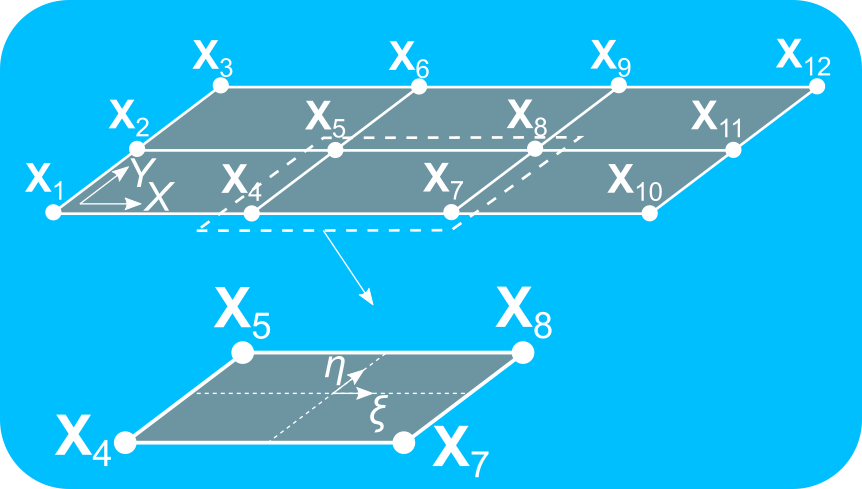

## Set-up Set-up the two-dimensional bilinear Lagrange Polynomials in physical space


$$l^{\text{Q}_1}_{i,j}(X, Y) = \prod_{1 \le m \le 2, m \neq j} \frac{X - X_m}{X_i - X_m} \prod_{1 \le n \le 2, n \neq j} \frac{Y - Y_n}{Y_i - Y_n}$$


 **Reflect**

Can this product rule in the physical space be used to construct an unstructured quadrilateral mesh?

### Choice of element for displaying the basis functions in the physical space

elQ1 = 3;

### Visualization of the bilinear basis functions in the physical space of the selected element in the bilinear quadratic mesh

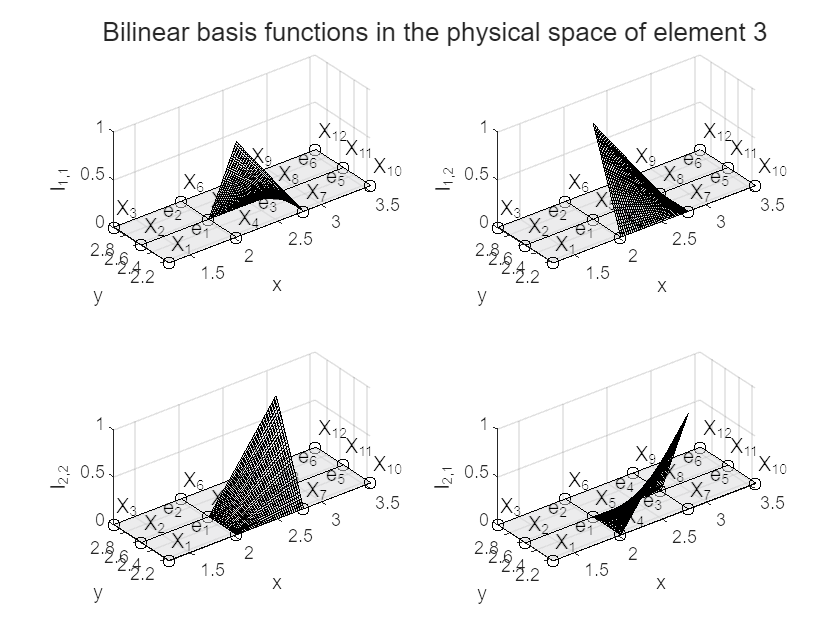

t2 = plot2dBilinearLagrangePolynomialsOnPhysicalSpace ...
    (elQ1, mshQ1, numVertices, l1L1, l2L1, ij);

## Two-dimensional bilinear Lagrange Polynomials in parametric space

The parametric space in this case is given as $(\xi,\eta) \in [-1, 1]^2$, leveraging symmetry, see the figure below:

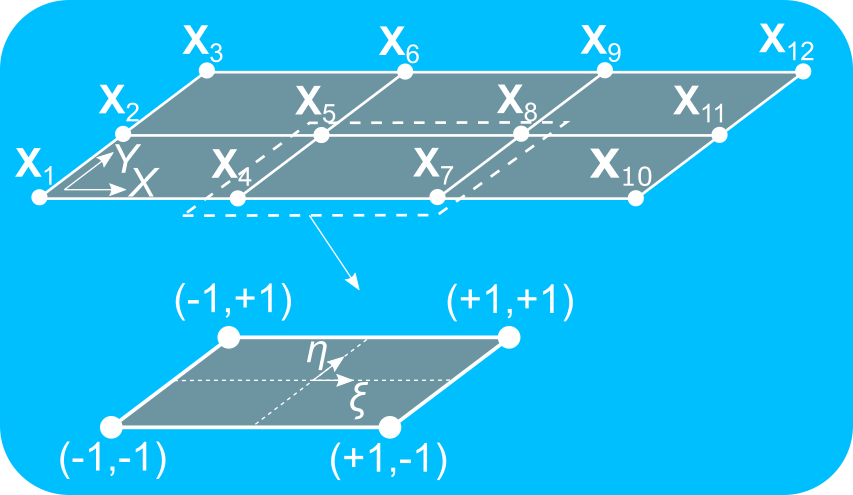

### Set-up of the two-dimensional bilinear Lagrange Polynomials in the parametric space

syms l11Q1(xi, eta) l12Q1(xi, eta) l22Q1(xi, eta) l21Q1(xi, eta)
l11Q1(xi, eta) = l1L1(xi, -1, +1)*l1L1(eta, -1, +1);
l12Q1(xi, eta) = l1L1(xi, -1, +1)*l2L1(eta, -1, +1);
l22Q1(xi, eta) = l2L1(xi, -1, +1)*l2L1(eta, -1, +1);
l21Q1(xi, eta) = l2L1(xi, -1, +1)*l1L1(eta, -1, +1);
lijQ1 = {l11Q1, l12Q1, l22Q1, l21Q1};

### Display the two-dimensional bilinear Lagrange Polynomials in the parametric space


$$N_1^{Q_1}(\xi, \eta) = \frac{1}{4} \left( 1 - \xi \right) \left( 1 - \eta \right), \quad (\xi,\eta) \in [-1, 1]^2, \\
N_2^{Q_1}(\xi, \eta) = \frac{1}{4} \left( 1 - \xi \right) \left( 1 + \eta \right), \quad (\xi,\eta) \in [-1, 1]^2, \\
N_3^{Q_1}(\xi, \eta) = \frac{1}{4} \left( 1 + \xi \right) \left( 1 + \eta \right), \quad (\xi,\eta) \in [-1, 1]^2, \\
N_4^{Q_1}(\xi, \eta) = \frac{1}{4} \left( 1 + \xi \right) \left( 1 - \eta \right), \quad (\xi,\eta) \in [-1, 1]^2,$$


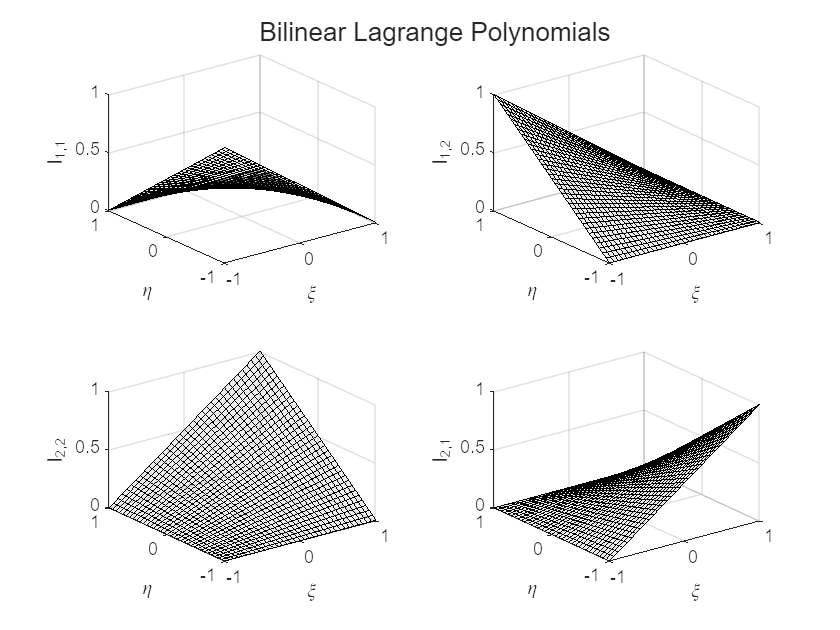

t3 = tiledlayout(2, 2);
for ii = 1:numel(lijQ1)
    nexttile
    fsurf(lijQ1{ii}, [-1 1 -1 1], "FaceColor", [217, 218, 219]./255, ...
        "FaceAlpha", 0.5);
    xlabel("\xi")
    ylabel("\eta")
    zlabel(sprintf("l_{%s}", num2str(ij(ii))))
end
title(t3, "Bilinear Lagrange Polynomials");